Setup

clear all

Parameters

% Independent
dt = 0.1;        % Timestep
duration = 300;  % Simulation duration

I = [1.0, 1.0, 0.5]';  % Moment of intertia (Normalised)
R = [1.0, 0.0, 0.0]';  % Centre of mass (Normalised)

n_0 = [0.8, 0.6, 0.0]';  % n ICs (Normalised if norm 1)
l_0 = [2.0, 0.0, 0.2]';  % l ICs (Need not be normalised)

H = @(n, l) R'*n + 1/2./I'*l.^2;  % Hamiltonian
    dH_dx = @(n, l) [R', l'./I'];
L      = @(n, l) sum(n.*l);  % Angular momentum
    dL_dx = @(n, l) [l', n'];
n_norm = @(n, l) sum(n.^2);  % n norms
    dn_norm_dx = @(n, l) [2*n', zeros(1, 3)];
K      = @(n, l) (- 2*n(1, :) + (l(1, :).^2 - l(2, :).^2)).^2 ...
               + (- 2*n(2, :) + 2*l(1, :).*l(2, :)       ).^2;  % Kovalevskaya invariant
    dK_dx = @(n, l) 4*[ ...
        - (- 2*n(1) + (l(1)^2 - l(2)^2)), ...
        - (- 2*n(2) + 2*l(1)*l(2)), ...
        0, ...
        + (- 2*n(1) + (l(1)^2 - l(2)^2))*l(1) + (- 2*n(2) + 2*l(1)*l(2))*l(2), ...
        - (- 2*n(1) + (l(1)^2 - l(2)^2))*l(2) + (- 2*n(2) + 2*l(1)*l(2))*l(1), ...
        0, ...
    ];

xi_1 = @(n, l) - 2*n(1, :) + (l(1, :).^2 - l(2, :).^2);  % Root Kovalevskaya invariants
xi_2 = @(n, l) - 2*n(2, :) + 2*l(1, :).*l(2, :);

Pois = @(n, l) [zeros(3),    mat_skew(n);
                mat_skew(n), mat_skew(l)];  % Skew-symmetric Poisson matrix

s = 10;  % No. of (Clenshaw--Curtis) quadrature points (for FET methods)


% Dependent
ts = 0:dt:duration;  % Time vector
N  = numel(ts);      % No. of time steps + 1

H_0      = H(n_0, l_0);  % Initial invariant values
L_0      = L(n_0, l_0);
n_norm_0 = n_norm(n_0, l_0);
K_0      = K(n_0, l_0);

[taus, ws] = ClenCurtPts(s, 0, 1);  % (Clenshaw--Curtis) quadrature points/weights

Timestepping schemes

% Implicit midpoint method
n_midpoint = zeros(3, N);  % n for implicit midpoint
l_midpoint = zeros(3, N);  % l for implicit midpoint

n_midpoint(:, 1) = n_0;  % Initial n
l_midpoint(:, 1) = l_0;  % Initial l

for n = 2:N
    % Compute delta_n and delta_l
    n_start = n_midpoint(:, n-1);
    l_start = l_midpoint(:, n-1);

    res = @(delta_x) ...
        res_midpoint( ...
            delta_x, ...
            [n_start; l_start], ...
            @(x) Pois(x(1:3), x(4:6))*dH_dx(x(1:3), x(4:6))', ...
            dt ...
        );

    delta_x = fsolve( ...
        res, ...
        double(Pois(n_start, l_start)*dH_dx(n_start, l_start)')*dt, ...
        optimoptions('fsolve', 'Display', 'off') ...
    );

    % Update n and l
    n_midpoint(:, n) = n_midpoint(:, n-1) + delta_x(1:3);
    l_midpoint(:, n) = l_midpoint(:, n-1) + delta_x(4:6);
end


% Fully conservative FET method
n_FET = zeros(3, N);  % n for fully conservative FET
l_FET = zeros(3, N);  % l for fully conservative FET

n_FET(:, 1) = n_0;  % Initial n
l_FET(:, 1) = l_0;  % Initial l

for n = 2:N
    % Compute delta_n and delta_l
    n_start = n_FET(:, n-1);
    l_start = l_FET(:, n-1);

    res = @(delta_x) ...
        res_FET( ...
            delta_x, ...
            [n_start; l_start], ...
            @(x) Pois(x(1:3), x(4:6)), @(x) dH_dx(x(1:3), x(4:6)), ...
            3, @(x) [ ...
                     dL_dx(x(1:3), x(4:6));
                dn_norm_dx(x(1:3), x(4:6));
                     dK_dx(x(1:3), x(4:6));
            ], ...
            taus, ws, ...
            dt ...
        );

    delta_x = fsolve( ...
        res, ...
        double(Pois(n_start, l_start)*dH_dx(n_start, l_start)')*dt, ...
        optimoptions('fsolve', 'Display', 'off') ...
    );

    % Update n and l
    n_FET(:, n) = n_FET(:, n-1) + delta_x(1:3);
    l_FET(:, n) = l_FET(:, n-1) + delta_x(4:6);
end

Plotting

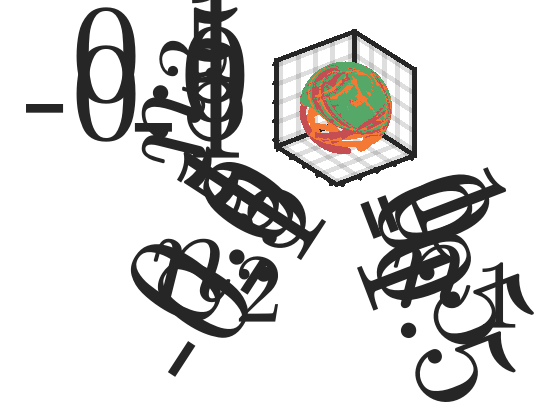

% Trajectories (Midpoint)
K_error = abs(K(n_midpoint, l_midpoint) - K(n_0, l_0));

n_midpoint_terrible = n_midpoint;
n_midpoint_terrible(:, K_error <= 1.5) = NaN;
n_midpoint_bad = n_midpoint;
n_midpoint_bad(:, K_error >= 1.5037) = NaN;
n_midpoint_bad(:, K_error <= 0.99845) = NaN;
n_midpoint_medium = n_midpoint;
n_midpoint_medium(:, K_error >= 1.0) = NaN;
n_midpoint_medium(:, K_error <= 0.5) = NaN;
n_midpoint_good = n_midpoint;
n_midpoint_good(:, K_error >= 0.50035) = NaN;

figure
plot3(n_midpoint_bad(1, :),    n_midpoint_bad(2, :),    n_midpoint_bad(3, :), ...
    'Color', '#C44E52', ...
    'LineWidth', 10)
hold on
plot3(n_midpoint_medium(1, :), n_midpoint_medium(2, :), n_midpoint_medium(3, :), ...
    'Color', '#F47935', ...
    'LineWidth', 10)
plot3(n_midpoint_good(1, :),   n_midpoint_good(2, :),   n_midpoint_good(3, :), ...
    'Color', '#55A868', ...
    'LineWidth', 10)
hold off
axis equal
box on
grid on
set(gca, 'FontSize', 240)
set(gca, 'TickLabelInterpreter', 'latex')
axis = gca;
xlim([-1.125 1.125])
xticks(linspace(-1, 1, 5))
xlabel('$n_1$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.XLabel.Position = [0.125 -1.5 -1.5];
ylim([-1.125 1.125])
yticks(linspace(-1, 1, 5))
ylabel('$n_2$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.YLabel.Position = [-1.5 0.125 -1.5];
zlim([-1.125 1.125])
zticks(linspace(-1, 1, 5))
zlabel('$n_3$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.ZLabel.Position = [-1.5 1.5 0.125];
set(axis, 'LineWidth', 8)

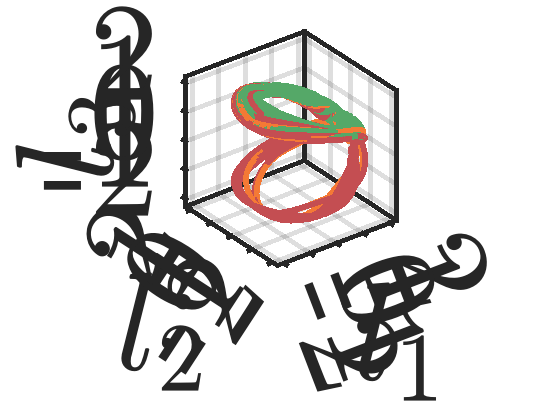


l_midpoint_bad = l_midpoint;
l_midpoint_bad(:, K_error <= 0.99845) = NaN;
l_midpoint_medium = l_midpoint;
l_midpoint_medium(:, K_error >= 1.0) = NaN;
l_midpoint_medium(:, K_error <= 0.5) = NaN;
l_midpoint_good = l_midpoint;
l_midpoint_good(:, K_error >= 0.50035) = NaN;

figure
plot3(l_midpoint_bad(1, :),    l_midpoint_bad(2, :),    l_midpoint_bad(3, :), ...
    'Color', '#C44E52', ...
    'LineWidth', 10)
hold on
plot3(l_midpoint_medium(1, :), l_midpoint_medium(2, :), l_midpoint_medium(3, :), ...
    'Color', '#F47935', ...
    'LineWidth', 10)
plot3(l_midpoint_good(1, :),   l_midpoint_good(2, :),   l_midpoint_good(3, :), ...
    'Color', '#55A868', ...
    'LineWidth', 10)
hold off
axis equal
box on
grid on
set(gca, 'FontSize', 240)
set(gca, 'TickLabelInterpreter', 'latex')
axis = gca;
xlim([-2.25 2.25])
xticks(linspace(-2, 2, 5))
xlabel('$l_1$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.XLabel.Position = [0.25 -2.75 -2.75];
ylim([-2.25 2.25])
yticks(linspace(-2, 2, 5))
ylabel('$l_2$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.YLabel.Position = [-2.75 0.25 -2.75];
zlim([-2.25 2.25])
zticks(linspace(-2, 2, 5))
zlabel('$l_3$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.ZLabel.Position = [-2.75 2.75 0.25];
set(axis, 'LineWidth', 8)

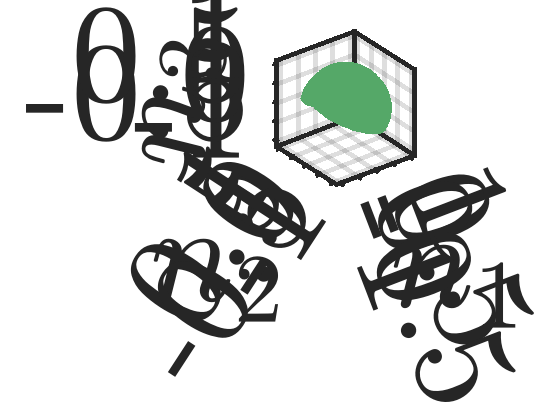



% Trajectories (FET)
figure
plot3(n_FET(1, :), n_FET(2, :), n_FET(3, :), ...
    'Color', '#55A868', ...
    'LineWidth', 10)
axis equal
box on
grid on
set(gca, 'FontSize', 240)
set(gca, 'TickLabelInterpreter', 'latex')
axis = gca;
xlim([-1.125 1.125])
xticks(linspace(-1, 1, 5))
xlabel('$n_1$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.XLabel.Position = [0.125 -1.5 -1.5];
ylim([-1.125 1.125])
yticks(linspace(-1, 1, 5))
ylabel('$n_2$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.YLabel.Position = [-1.5 0.125 -1.5];
zlim([-1.125 1.125])
zticks(linspace(-1, 1, 5))
zlabel('$n_3$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.ZLabel.Position = [-1.5 1.5 0.125];
set(axis, 'LineWidth', 8)

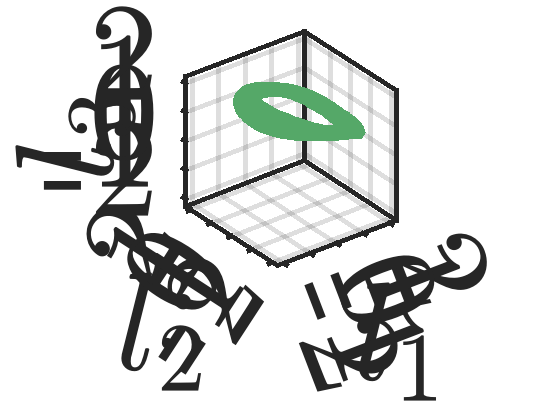


figure
plot3(l_FET(1, :), l_FET(2, :), l_FET(3, :), ...
    'Color', '#55A868', ...
    'LineWidth', 10)
axis equal
box on
grid on
set(gca, 'FontSize', 240)
set(gca, 'TickLabelInterpreter', 'latex')
axis = gca;
xlim([-2.25 2.25])
xticks(linspace(-2, 2, 5))
xlabel('$l_1$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.XLabel.Position = [0.25 -2.75 -2.75];
ylim([-2.25 2.25])
yticks(linspace(-2, 2, 5))
ylabel('$l_2$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.YLabel.Position = [-2.75 0.25 -2.75];
zlim([-2.25 2.25])
zticks(linspace(-2, 2, 5))
zlabel('$l_3$', 'Interpreter', 'latex', ...
    'FontSize', 240)
axis.ZLabel.Position = [-2.75 2.75 0.25];
set(axis, 'LineWidth', 8)

Functions

function mat = mat_skew(vec)
    mat = zeros(3, 3);
    for i = 1:3
    for j = 1:3
    for k = 1:3
        mat(i, j) = mat(i, j) + ...
            det(double([(1:3 == i); (1:3 == j); (1:3 == k)]))*vec(k);
    end
    end
    end
end

Residual functions

% Impicit midpoint residual
function res = res_midpoint( ...
            delta_x, ...
            start_x, ...
            f, ...
            dt ...
        )    
    mid_x = start_x + delta_x/2;

    res = ...
          delta_x/dt ...
        - f(mid_x);
end


% Fully conservative FET residual
function res = res_FET( ...
            delta_x, ...
            start_x, ...
            Pois, dH_dx, ...
            no_invars, dinvar_dx, ...
            taus, ws, ...
            dt ...
        )
    x_dim = size(start_x, 1);
        s = size(taus, 1);

    % x at quadrature points
    tau_x = start_x + delta_x*taus';

    % Evaluate auxiliary functions
        dH_dx_aux = zeros(1,         x_dim);
    dinvar_dx_aux = zeros(no_invars, x_dim);
    for i = 1:s
            dH_dx_aux =     dH_dx_aux +     ws(i)*dH_dx(tau_x(:, i));
        dinvar_dx_aux = dinvar_dx_aux + ws(i)*dinvar_dx(tau_x(:, i));
    end

    % Shifted Poisson matrix to ensure invariant orthogonality
    % (Minimum perturbation under Frobenius norm)
         mat_aux = dinvar_dx_aux*(norm(dH_dx_aux)^2*eye(x_dim) - dH_dx_aux'*dH_dx_aux)*dinvar_dx_aux';
            lamb = @(x) mat_aux\(dinvar_dx_aux*Pois(x)*dH_dx_aux');
    shifted_Pois = @(x) Pois(x) + ...
        (dH_dx_aux'*lamb(x)'*dinvar_dx_aux) - (dH_dx_aux'*lamb(x)'*dinvar_dx_aux)';

    % Residual
    res = delta_x/dt;
    for i = 1:s
        res = res - ...
            ws(i)*shifted_Pois(tau_x(:, i))*dH_dx_aux';
    end
end

Quadrature functions

% Clenshaw--Curtis points/weights
function [x, w] = ClenCurtPts(N1, a, b)
    N = N1 - 1;
    bma = b - a;
    c = zeros(N1,2);
    c(1:2:N1,1) = (2./[1, 1-(2:2:N).^2])';
    c(2,2) = 1;
    f = real(ifft([c(1:N1, :); c(N:-1:2, :)]));

    x = 0.5*((b + a) + N*bma*f(1:N1, 2));
    w = bma*([f(1, 1); 2*f(2:N, 1); f(N1, 1)])/2;
end